## Forward Tutorial

Get the simulation settings

run("../CIRLSetup.m")

HR settings of a Bead for Tunable system

[ psfpar, psfpari ] = PSFConfigNoAber();
X     = 200;        % discrete lateral size in voxels
Y     = 200;        % discrete lateral size in voxels
Z     = 200;        % discrete axial size in voxels
dXY   = 0.0125;     % lateral voxel scaling in microns ---- for 20X lens (6.4/20)....for 60X lens (6.4/63)
dZ    = 0.0125;     % axial voxel scaling in microns
uc    = 2*psfpar.NA/psfpari.v(1);  % cycle/um
offs  = 0; % [0, 0, 0];
phi   = [0, 1, 2]*(2*180)/3;
theta = 0; %[0, 60, 120];
u     = 0.8*uc; %[0.8, 0.8, 0.8]*uc;
x0    = 0.326;  % in mm
fL1   = 100;  % in mm
fL2   = 250;  % in mm
fMO   = 160/63;
w     = ((x0*fL2)/(2*fL1*fMO))*u;
phizDeg   = 46.0;
Nslits = 3;

HR point spread function

h  = PSFAgard( X, Z, dXY, dZ);

HR modulating pattern

[im, jm, ~] = PatternTunable3DNSlits(X, Y, Z, u, w, dXY, dZ, phi, offs, theta, phizDeg, Nslits);

HR bead object construction

Radius    = 1/2;
Thickness = 0.5/2;
ob        = SphericalShell(X, Y, Z, dXY, Radius, Thickness);

Analysis of HR bead object

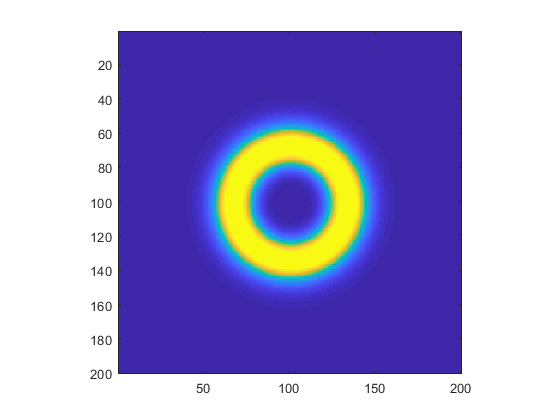

figure; imagesc(ob(:,:,1+Z/2)); axis square;

HR forward images

g  = ForwardModel(ob, h, im, jm);

Analysis of HR forward images

[Y, X, Z, Nthe, Nphi] = size(g)

Y = 200

X = 200

Z = 200

Nthe = 1

Nphi = 3

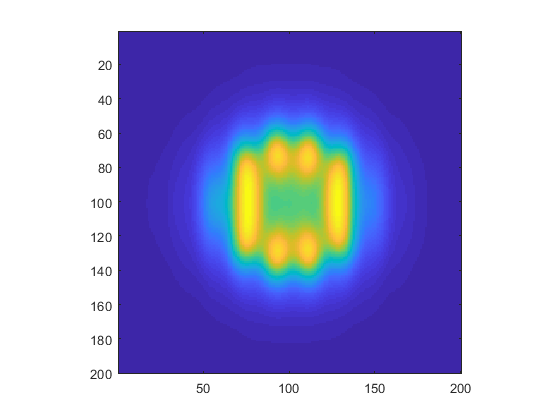

curTheInd = 1;
curPhiInd = 1;
figure; imagesc(g(:,:,1+Z/2,curTheInd,curPhiInd)); axis square;